defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Supp - RemovalCtxEvents\');


## load

wtFiles = loadFileList('..\Figure 3 - Ablations\Data\WILDTYPE\*\*ICinfo16_dFoF.mat');
data = corticalPeaksQuant(wtFiles);

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-265\ICinfo16_dFoF.mat


sizeR = 6

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-314_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 20

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-330_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 9

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-337\ICinfo16_dFoF.mat


sizeR = 10

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-342_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 5

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-495_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 10

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-569_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 18

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-571_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 14

M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 3 - Ablations\Data\WILDTYPE\Experiment-974_Snap25GC6s\ICinfo16_dFoF.mat


sizeR = 7

mean(cell2mat({data(:).ctxEvents})/10)
sterr(cell2mat({data(:).ctxEvents})/10,2)

warning('off', 'MATLAB:imagesci:tiffmexutils:libtiffErrorAsWarning')
imgFile = loadFileList('.\Data\*342*.tif');
img = loadTif(imgFile{1},8);

## analyze and generate

wtFileNum = find(contains(wtFiles,'342'));
timeIndex = data(wtFileNum).killLocs(5);

peakImg = timeIndex - 2900

peakImg = 114

times = [peakImg-35:10:peakImg+35]

times =     79    89    99   109   119   129   139   149


for i = 1:8
    figure;
    imagesc(img(:,:,times(i)));
    colormap gfb;
    caxis([25 230]);
    truesize;
    box off;
    axis off;
    set(gcf,'color','none');
    set(gca,'LooseInset',get(gca,'TightInset'));
    export_fig(['.\EPS Panels\' num2str(i) '_imgSeq.eps'], '-eps');
end

## more plot

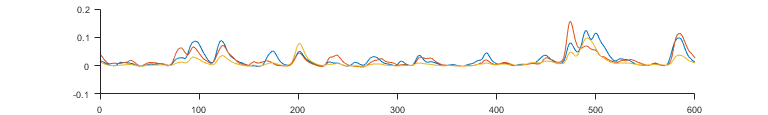



figure;
time = [1:1:70];
before = 200;
after = 400;
plot(data(wtFileNum).signals(timeIndex-before:timeIndex+after,1)); hold on;
plot(data(wtFileNum).signals(timeIndex-before:timeIndex+after,2));
plot(data(wtFileNum).signals(timeIndex-before:timeIndex+after,3));
xlim([0 600]);
figQuality(gcf,gca,[8 1.2]);
export_fig(['.\EPS Panels\rawTrace.eps'], '-eps');